# Signal after MAX2771

rawdata = repmat([1 0 1 1 0 1 0 0 0 1],1,5);

fd      = 50;               % Data frequency
fca     = 1.023e6;          % C/A code frequency
fs      = 20*fca;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;        % BPSK(1) fc = n*1.023e6; 
%code rate BPSK(n) 
%                 spreading code rate n*1.023 MHz
codeLength = round(1023/n); 
cd_delay = 64;
fdoppler = [0, 30, -20, -50];
ca_codes = [ 1,  8,  20, 12];

Rsignal = .5*(Received_Simplified(rawdata,fca,fs,...
    fdoppler(1),ca_codes(1),1,cd_delay));
[I,Q, clk] = MAX2771_simplified(Rsignal, fs,...
    round(2), true);

IQ = I + 1i*Q;

## Defining the PLL tracking loop

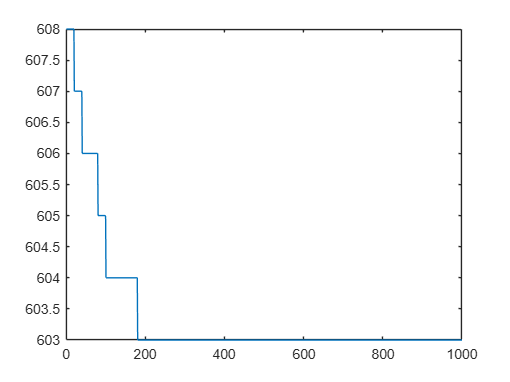

block_size = length(IQ)/(20*length(rawdata));
[IE, QE, IP, QP, IL, QL] = ...
    deal(zeros(1,length(IQ)/block_size));

nco_out = exp(-1i.*2.*pi.*fdoppler(1) ...
    .*(0:length(IQ)-1)./clk);

T_PID = block_size/clk;
spacing = length(IQ)/(2*20*length(rawdata)*1023);
cd_phase = round(2*spacing*cd_delay*.95);

gc = data_mapper(gold_code_L1(codeLength,1));
gc = expand(gc,20*length(rawdata));
gc = upsampler(gc,length(IQ)/length(gc));

gc = circshift(gc, cd_phase);
gce = circshift(gc, -spacing);
gcl = circshift(gc, spacing);

IQ_data = zeros(1,length(IQ));
[filter_out, ca_phase_rec] = ...
    deal(zeros(1,length(IQ)/block_size));
[filter_in, filt_I] = ...
    deal(zeros(1,length(IQ)/block_size+1));

Kp = 3;
Kd = .0;
Ki = .3;

delta = 10;

for i = 1:length(IQ)/block_size
    idx = (1:block_size) + (i - 1) * block_size;
    
    correlated_E = IQ(idx) .* gce(idx) .* nco_out(idx);
    correlated_P = IQ(idx) .* gc(idx) .* nco_out(idx);
    correlated_L = IQ(idx) .* gcl(idx) .* nco_out(idx);

    IQ_data(idx) = correlated_P;

    IE(i) = sum(real(correlated_E));
    QE(i) = sum(imag(correlated_E));
    IP(i) = sum(real(correlated_P));
    QP(i) = sum(imag(correlated_P));
    IL(i) = sum(real(correlated_L));
    QL(i) = sum(imag(correlated_L));
    
    filter_in(i+1) = .95*code_discriminator(IE(i),QE(i), ...
        IP(i),QP(i),IL(i),QL(i)) + .05*filter_in(i);
    filt_I(i+1) = Ki*filter_in(i+1) + filt_I(i);
    filt_D = Kd*(filter_in(i+1)-filter_in(i));
    filter_out(i) = Kp*filter_in(i+1) + ...
        filt_I(i+1) + filt_D;
    %filter_out(i) = sign(filter_out(i)) * ...
    % min(abs(filter_out(i)), delta);
    cd_phase = cd_phase + round(filter_out(i));
    ca_phase_rec(i) = cd_phase;

    gc = circshift(gc,round(filter_out(i)));
    gce = circshift(gc,-spacing);
    gcl = circshift(gc, spacing);

    % """
end

figure Name checking; plot(ca_phase_rec);

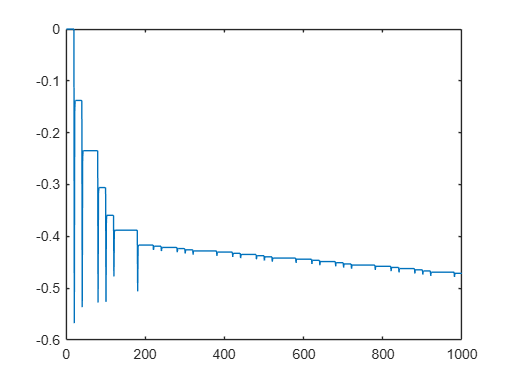

figure Name filter; plot(filter_out)

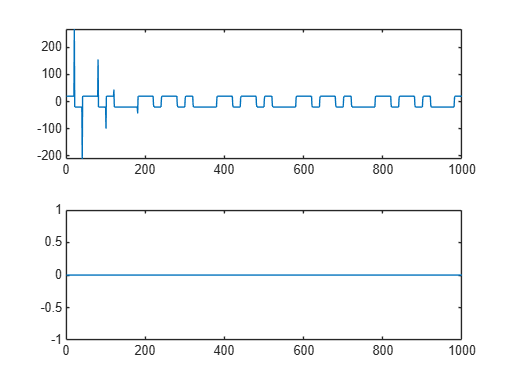

figure Name correlator;
subplot(2,1,1); plot(IP);
subplot(2,1,2); plot(QP);

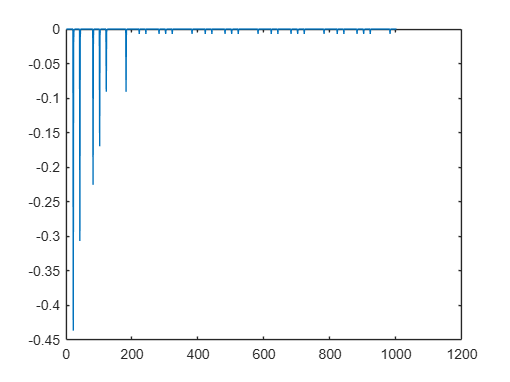

figure; plot(filter_in);

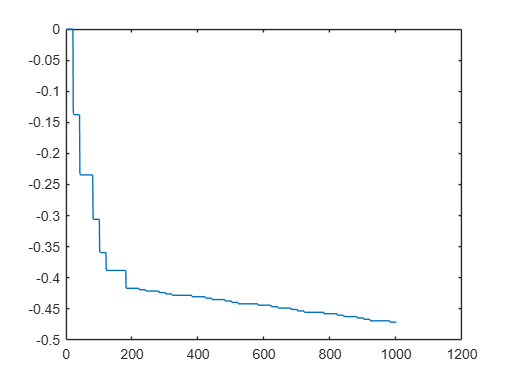

figure; plot(filt_I);

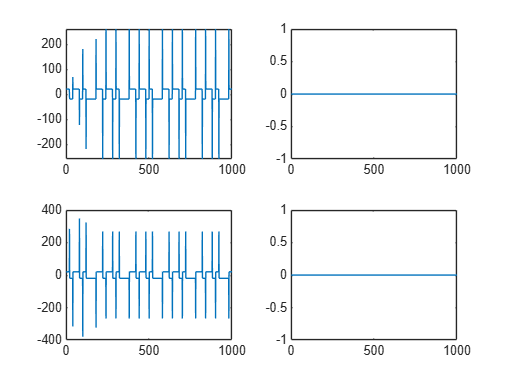

figure Name correlators;
subplot(2,2,1); plot(IE);
subplot(2,2,2); plot(QE);
subplot(2,2,3); plot(IL);
subplot(2,2,4); plot(QL);

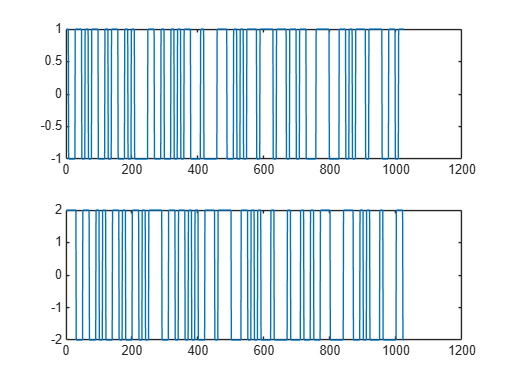

figure;
subplot(2,1,1); plot(gc(1:1023));
subplot(2,1,2); plot(I(1:1023));